clear 
clc

syms M_c m g l r real
syms tau
syms x(t) theta(t) x_dot theta_dot x_ddot theta_ddot

params = [M_c; m; g; l; r];
values = [0.3; 0.1; 9.82; 0.03; 0.025];

% Differentiated variables
vars_diff = [diff(x,t,2); diff(x); x; diff(theta,t,2); diff(theta); theta];

% Inverse pendulum mass dynamics
posx_m = l*sin(theta) + x;
accx_m = diff(posx_m, t, 2); % second derivative

% Force required to accelerate the pendulums' mass  
F_pend = m*accx_m;

% The force applied on the "cart" is
% the force generated by the motors
% minus the reaction force from the pendulum mass (x component)
F_mot = tau/r;
eq1 = M_c*diff(x,t,2) == F_mot - F_pend;

% Considering the load to be a point mass
eq2 = m*l^2*diff(theta,t,2) == m*g*l*sin(theta) - m*l*diff(x,t,2)*cos(theta) - tau;

% Collect terms
eq1 = collect(lhs(eq1) - rhs(eq1), vars_diff);
eq2 = collect(lhs(eq2) - rhs(eq2), vars_diff);

% Express symbolically
syms x theta
vars_sym = [x_ddot; x_dot; x; theta_ddot; theta_dot; theta];
eq1 = subs(eq1, vars_diff, vars_sym);
eq2 = subs(eq2, vars_diff, vars_sym);

% Get nonlinear equations
q = [x; theta];
q_dot = [x_dot; theta_dot];
q_ddot = [x_ddot; theta_ddot];

symb_states = [q; q_dot; tau];

[M, rest] = equationsToMatrix([eq1; eq2], [x_ddot; theta_ddot]);
model_nonlin_symb = M \ rest;
model_nonlin = subs(model_nonlin_symb, formula(params), values);

pendulum_dynamics = matlabFunction(model_nonlin, 'Vars', {x, theta, x_dot, theta_dot, tau})

pendulum_dynamics = function_handle with value:
    @(x,theta,x_dot,theta_dot,tau)[((tau.*(3.0./1.0e+2)+theta_dot.^2.*sin(theta).*2.25e-6-cos(theta).*sin(theta).*7.365e-4+(tau.*cos(theta))./4.0e+1).*(-1.333333333333333e+3))./(cos(theta).^2./1.0e+1-2.0./5.0);((tau./1.0e+2-sin(theta).*2.946e-4+tau.*cos(theta).*(3.0./1.0e+3)+theta_dot.^2.*cos(theta).*sin(theta).*2.25e-7).*4.444444444444444e+5)./(cos(theta).^2./1.0e+1-2.0./5.0)]



% Get linearized M C G and B terms (first order TS)
% Linearize before inverting the M matrix

q_op = [0; 0];
q_dot_op = [0; 0];
tau_op = 0;

B = jacobian(rest, tau); % extract tau terms
rest_noinput = simplify(rest + B*tau); % remove input from rest terms

M0 = subs(M, formula([q; q_dot]), [q_op; q_dot_op]);
B0 = subs(B, formula([q; q_dot]), [q_op; q_dot_op]); % Already linear, but for completeness

G_nonlin = jacobian(rest_noinput, q);     % "stiffness" term
C_nonlin = jacobian(rest_noinput, q_dot); % "damping" term

% linearize at op point
G_lin = subs(G_nonlin, formula([q; q_dot]), [q_op; q_dot_op]);
C_lin = subs(C_nonlin, formula([q; q_dot; tau]), [q_op; q_dot_op; tau_op]);

A21 = simplify(M0 \ G_lin)

$$A21 = \left(\begin{array}{cc} 0 & -\frac{g\,m}{M_{c}}\\ 0 & \frac{g\,\left(M_{c}+m\right)}{M_{c}\,l} \end{array}\right)$$

A22 = simplify(M0 \ C_lin)

$$A22 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

B_lin = simplify(M0 \ B0);

% Create first order state space model.
% states x, theta, x_dot, theta_dot
A_symbolic = [zeros(2), eye(2);
              -A21, -A22]

$$A\_symbolic = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & \frac{g\,m}{M_{c}} & 0 & 0\\ 0 & -\frac{g\,\left(M_{c}+m\right)}{M_{c}\,l} & 0 & 0 \end{array}\right)$$

B_symbolic = [zeros(2,1); B_lin]

$$B\_symbolic = \left(\begin{array}{c} 0\\ 0\\ \frac{l+r}{M_{c}\,l\,r}\\ -\frac{M_{c}\,r+l\,m+m\,r}{M_{c}\,l^{2}\,m\,r} \end{array}\right)$$


A = double(subs(A_symbolic, formula(params), values))

A =          0         0    1.0000         0
         0         0         0    1.0000
         0    3.2733         0         0
         0 -436.4444         0         0


B = double(subs(B_symbolic, formula(params), values))

B = 1.0e+04 *

         0
         0
    0.0244
   -1.9259


C = eye(4);

sys = ss(A,B,C,0);

Obsv = rank(obsv(sys))

Obsv = 4

Cont = rank(ctrb(sys))

Cont = 4


Qx = [1, 0, 0, 0;
      0, 100, 0, 0;
      0, 0, 1, 0;
      0, 0, 0, 1];
Qu = 0.01;
[K, ~, ~] = lqr(sys, Qx, Qu, 0)

K =    10.0000 -106.8954   32.3049   -9.5913



eig(A-B*K)

ans = 1.0e+05 *

  -1.9261 + 0.0000i
  -0.0001 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i


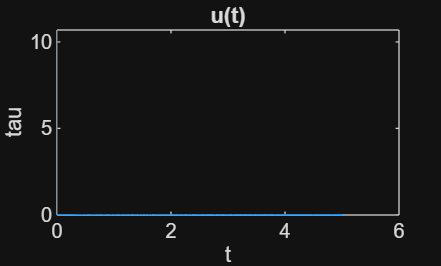


controller = @(z) -K*z;

ode = @(t, z) [
    z(3);
    z(4);
    pendulum_dynamics(z(1), z(2), z(3), z(4), controller(z))
];

[t, Z] = ode45(ode, [0 5], [0; 0.1; 0; 0]);

U = zeros(length(t),1);
for i=1:length(t)
  U(i) = controller(Z(i,:)');
end
figure; plot(t,U); xlabel('t'); ylabel('tau'); title('u(t)');

disp(['max|u| = ', num2str(max(abs(U)))])

max|u| = 10.6895


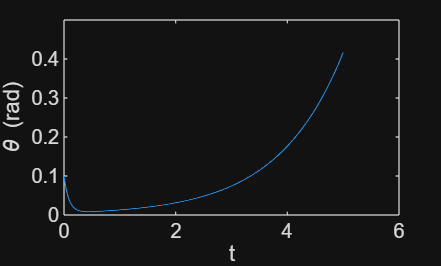


figure(1)
plot(t, Z(:,2)); xlabel('t'); ylabel('\theta (rad)')